% 论文方法的对照组 基于能量 20220804 YMC SDD-GLRT
close all
clear
clc

## 参数设置

pfa         = 0.0001;
num_range_cells = 210;
Para.J      = 74;           % 目标所占距离单元数
Para.pfa    = pfa;           % 总虚警概率
Para.alfa   = 0.4;           % SSD-GLRT散射中心密度


## 数据读取

% 训练数据 杂波
Detector_train_data_add_ref = load('.\dataset_train.mat').train_data_cl;       
size(Detector_train_data_add_ref)  

ans =        18000         210           4


% 帧*4极化*距离单元
Detector_train_data_add_ref = permute(Detector_train_data_add_ref, [1, 3, 2]);
% 测试数据 杂波+目标
Detector_test_data_add_ref = load('.\dataset_test_1.mat').test_data;   % SCR*帧*4极化*距离单元
size(Detector_test_data_add_ref)

ans =           31        3600         210           4


Detector_test_data_add_ref=permute(Detector_test_data_add_ref,[1,2,4,3]);

## SDD-GLRT

% 极化通道融合 PWF or SPAN
% 极化协方差矩阵计算
[Pol_Sigma, wbldis] = get_pol_Covariance_matrix(Detector_train_data_add_ref(:,:,1:end-10));

SDDGLRT_pfa = nan(1, size(Detector_train_data_add_ref,1));
for j=1:size(Detector_train_data_add_ref,1)

    HRRP_test_temp = squeeze(Detector_train_data_add_ref(j,:,:));        
    [HRRP_test_temp_pwf] = func_PWF(HRRP_test_temp, Pol_Sigma);
    P_Echo = HRRP_test_temp_pwf(:,end-10).^2;
    P_Noise = mean(HRRP_test_temp_pwf(:,end-9:end).^2);
    if j==1 % 20230220怎加 if end 选择性跳过语句以加速
        Para.Threshold_ssd = 1 * get_sddglrt_th(num_range_cells,P_Noise,Para);
    end    
    Hastarget = ssdglrt(P_Echo,P_Noise,Para);

    SDDGLRT_pfa(1,j) = Hastarget;

end
mean(SDDGLRT_pfa)

ans = 0



SDDGLRT_result = nan(size(Detector_test_data_add_ref,1), size(Detector_test_data_add_ref,2));

% [MNdetector_Th1, MNdetector_Pfcell] = MNdetector_get_param(pfa, MNdetector_Th2_list(k), wbldis);
for i=1:size(Detector_test_data_add_ref,1)
% for i=10:13
    i
    for j=1:size(Detector_test_data_add_ref,2)
        HRRP_test_temp = squeeze(Detector_test_data_add_ref(i,j,:,:));        
        [HRRP_test_temp_pwf] = func_PWF(HRRP_test_temp, Pol_Sigma);
        P_Echo = HRRP_test_temp_pwf(:,1:end-10).^2;
        P_Noise = mean(HRRP_test_temp_pwf(:,end-9:end).^2);
        if j==1 % 20230220怎加 if end 选择性跳过语句以加速
            Para.Threshold_ssd = 1 * get_sddglrt_th(num_range_cells,P_Noise,Para);
        end     
        Hastarget = ssdglrt(P_Echo,P_Noise,Para);

        SDDGLRT_result(i,j) = Hastarget;

    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

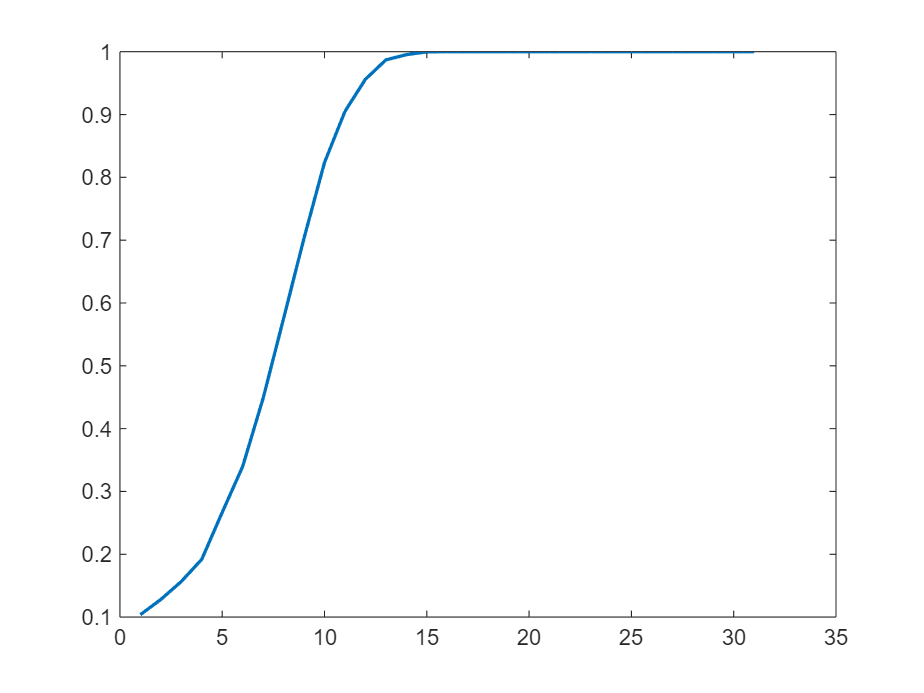

figure;
plot(mean(SDDGLRT_result,2)', 'LineWidth', 1.5);

% save('./Result/SDDGLRT_result.mat', 'SDDGLRT_result');

## 子函数--获取极化协方差矩阵

function [Sigma, wbldis] = get_pol_Covariance_matrix(Cl_data)
% 420*4*33
HRRP_test = [];
for i=1:size(Cl_data,1)
    HRRP_test = cat(2, HRRP_test, squeeze(Cl_data(i,:,:)));
end
s_hh = HRRP_test(1,:);
s_vh = HRRP_test(3,:);
s_hv = HRRP_test(2,:);
s_vv = HRRP_test(4,:);
s_hh_p = HRRP_test(1,:) .* conj(HRRP_test(1,:)); 
s_vh_p = HRRP_test(3,:) .* conj(HRRP_test(3,:));
s_hv_p = HRRP_test(2,:) .* conj(HRRP_test(2,:)); 
s_vv_p = HRRP_test(4,:) .* conj(HRRP_test(4,:));
Sigma11 = mean(s_hh_p);
Sigma22 = mean(s_vh_p);
Sigma33 = mean(s_hv_p);
Sigma44 = mean(s_vv_p);
Sigma21 = mean(conj(s_hh).*s_vh);
Sigma31 = mean(conj(s_hh).*s_hv);
Sigma41 = mean(conj(s_hh).*s_vv);
Sigma32 = mean(conj(s_vh).*s_hv);
Sigma42 = mean(conj(s_vh).*s_vv);
Sigma43 = mean(conj(s_hv).*s_vv);
Sigma12 = mean(conj(s_vh).*s_hh);
Sigma13 = mean(conj(s_hv).*s_hh);
Sigma14 = mean(conj(s_vv).*s_hh);
Sigma23 = mean(conj(s_hv).*s_vh);
Sigma24 = mean(conj(s_vv).*s_vh);
Sigma34 = mean(conj(s_vv).*s_hv);
Sigma = [Sigma11,Sigma12,Sigma13,Sigma14;Sigma21,Sigma22,Sigma23,Sigma24;...
         Sigma31,Sigma32,Sigma33,Sigma34; Sigma41,Sigma42,Sigma43,Sigma44];

[hrrp_num, N_hrrp] = size(s_hh);
hrrp_pwf      = zeros(1, hrrp_num*N_hrrp);
for k=1:hrrp_num
    for L=1:N_hrrp
        hrrp_pwf((k-1)*N_hrrp+L) = real([s_hh(k,L);s_vh(k,L);s_hv(k,L);s_vv(k,L)]' ...
            * inv(Sigma) * [s_hh(k,L);s_vh(k,L);s_hv(k,L);s_vv(k,L)]);
    end
end
% hrrp_pwf = hrrp_pwf ./ mean(hrrp_pwf) ;
wbldis = wblfit((hrrp_pwf), 0.05);
p_1 = wbldis(1);
q_1 = wbldis(2);
end

## 子函数--极化白化滤波

function [HRRP_pwf] = func_PWF(HRRP_test, Sigma)
s_hh = HRRP_test(1,:);
s_vh = HRRP_test(3,:);
s_hv = HRRP_test(2,:);
s_vv = HRRP_test(4,:);
HRRP_pwf = zeros(size(s_hh));
for i = 1:length(s_hh)
    HRRP_pwf(1,i) = real([s_hh(i);s_vh(i);s_hv(i);s_vv(i)]' * inv(Sigma) * [s_hh(i);s_vh(i);s_hv(i);s_vv(i)]); %#ok<MINV> 
end
end

## 子函数--SDD-GLRT

function Hastarget=ssdglrt(P_Echo,P_Noise,Para)
beta=Para.alfa/(1-Para.alfa);
ssd_glrt=log(1+beta*exp(P_Echo/P_Noise));
Sumk=sum(ssd_glrt);
Hastarget=Sumk> Para.Threshold_ssd;
end

function Threshold = get_sddglrt_th(num_range_cells, noise_power, Para)
    scatter_density = Para.alfa;            %%%%%
    Pfa = Para.pfa;                    %%%%%
    %% SDD-GLRT的门限
    generator = @() stat(sqrt(noise_power)*white_gaussian_noise(1, num_range_cells), noise_power, scatter_density);
    N = ceil(33 / Pfa); % 20220808，100改成33
    Threshold = quantile_piecewise_parabolic(generator, 1 - Pfa, N);
    
    function statistics = stat(data, noise_power, alpha)
    beta = alpha/(1 - alpha);
    statistics = sum(log(1+beta*exp(abs(data).^2/noise_power)));
    end
    function noise = white_gaussian_noise(varargin)
%     noise = sqrt(1/2)*(randn(varargin{:})+1j*randn(varargin{:})); % 高斯
    noise = sqrt(1/2)*(wblrnd(2.1443,1.1318,varargin{:})+1j*wblrnd(2.1443,1.1318,varargin{:})); % 韦布尔
    noise = noise ./ mean(noise);  % 韦布尔
    end 
    function quantile = quantile_piecewise_parabolic(random_variable, p, N)
    x = arrayfun(@(n) random_variable(), 1:5);
    q = sort(x); 	% marker_heights
    n = 1:5;			% marker_positions
    dn = [0, p/2, p, (1+p)/2, 1];
    n1 = [1, 1 + 2*p, 1 + 4*p, 3 + 2*p, 5]; % (5 - 1)*dn + 1; desired_positions
    count = 5;
    while count < N
        % stem(q, n);
        % arrayfun(@(i) text(q(i), n(i), sprintf('n = %d', n(i)), 'HorizontalAlignment', 'center'), 1:5);
        % arrayfun(@(i) text(q(i), 0, sprintf('%0.2f', q(i)), 'HorizontalAlignment', 'center'), 1:5);
        x = random_variable();
        count = count + 1;
        k = find(q <= x, 1, 'last');
        if x < q(1)
            q(1) = x;
            k = 1;
        end
        if q(5) < x
            q(5) = x;
            k = 4;
        end
        n(k+1:5) = n(k+1:5) + 1;
        n1 = n1 + dn;
        for i = 2:4
            d_i = n1(i) - n(i);
            if (d_i >= 1 && n(i + 1) - n(i) > 1) || (d_i <= -1 && n(i-1) - n(i) < -1)
                d = sign(d_i);
                qi = q(i) + d_i / (n(i+1) - n(i-1)) * ((n(i) - n(i-1) + d)*(q(i+1) - q(i))/(n(i+1) - n(i)) + (n(i+1) - n(i) -d) * (q(i) - q(i-1)) / (n(i) - n(i-1)));
                if q(i - 1) < qi && qi < q(i+1)
                    q(i) = qi;
                else
                    q(i) = q(i) + d*(q(i+d) - q(i))/(n(i+d)-n(i));
                end
                n(i) = n(i) + d_i;%marker_position(i) = desired_position(i)
            end
        end
    end
    quantile = q(3);
    end
end